# Notebook 03: ANN Training

This research project contains 3 notebooks:

- Notebook 01: Project Overview

- Notebook 02: Preprocessing and Feature Extraction

- Notebook 03: ANN Training

You are currently running **Notebook 03**. Before running this notebook, you should have run Notebook 02 to generate features from the neural data.

## Step 0: Ensure you are in the correct directory

cd(fileparts(matlab.desktop.editor.getActiveFilename))

## Step 1: Load the neural features

Before proceeding, ensure you've run the last cell of the Feature Extraction section in `notebook 02`, which saves your neural features to the `results` folder in your workspace.

clearvars
load("datasets\training_dataset.mat")
load("results\features_binned.mat")
load("results\features_SES.mat")
load("results\features_RMS.mat")
load("results\features_ZC.mat")
load("results\features_ZCR.mat")

## Step 2: Determine the dimensions of the mapping

For this section, you have been provided with a Multilayer Feedforward Network. You are welcome to use your own architecture, but the explanations in this notebook only apply to the provided network.

Remember that a neural network can be thought of as a [universal function approximator.](https://www.cs.cmu.edu/~epxing/Class/10715/reading/Kornick_et_al.pdf) This means that your network learns a one-to-one mapping between your input vectors and your output vectors:


$$\vec{x_{out}} = f(\vec{x_{in}})$$


For this reason, you must ensure that the network has the same number of input vectors as output vectors during training.

Your output vectors are the hand's kinematics, which are a set of `N` vectors with dimensionality `1x2.`

Your input vectors are a set of `N` vectors with dimensionality `1xM`, where `M` is determined by your feature extraction methods.

`N,` in this case, corresponds to the number of samples in the `hand_kinematics` of the training set.

First, verify that your have the same number of samples for the features and the kinematics, which will act as our feature labels (i.e., the values we are trying to predict).  

feature_labels = training_data.hand_kinematics;

% Save our features in variables
features_binned = neural_features_binned;
features_SES = neural_features_SES;
features_RMS = neural_features_RMS;
features_ZC = neural_features_ZC;
features_ZCR = neural_features_ZCR;

% Check all of our feature extraction methods
assert(length(features_binned) == length(feature_labels));
assert(length(features_SES) == length(feature_labels));
assert(length(features_RMS) == length(feature_labels));
assert(length(features_ZC) == length(feature_labels));
assert(length(features_ZCR) == length(feature_labels));

How many outputs do we want? Well, that depends on the number of degrees of freedom we are predicting, which in our case is:

n_outputs = width(feature_labels)

n_outputs = 2

How many features per sample do you have in total? That depends on the choices you made in `notebook_02`, including but not limited to:

- How many channels (out of the six provided in the dataset) you decided to use

- How many features per channel you calculated

%Add number calculations for our features
n_features_binned = width(features_binned)

n_features_binned = 6

n_features_SES= width(features_SES)

n_features_SES = 6

n_features_RMS = width(features_RMS)

n_features_RMS = 6

n_features_ZC = width(features_ZC)

n_features_ZC = 6

n_features_ZCR = width(features_ZCR)

n_features_ZCR = 6

How many timestamps are there?

n_timestamps = length(feature_labels);

After providing this information, we know that **for every timestamp** in features:

fprintf('Binned features map a %dx1 vector to a %dx1 vector', n_features_binned, n_outputs)

Binned features map a 6x1 vector to a 2x1 vector


fprintf('SES features map a %dx1 vector to a %dx1 vector', n_features_SES, n_outputs)

SES features map a 6x1 vector to a 2x1 vector


fprintf('RMS features map a %dx1 vector to a %dx1 vector', n_features_RMS, n_outputs)

RMS features map a 6x1 vector to a 2x1 vector


fprintf('ZC features map a %dx1 vector to a %dx1 vector', n_features_ZC, n_outputs)

ZC features map a 6x1 vector to a 2x1 vector


fprintf('ZCR features map a %dx1 vector to a %dx1 vector', n_features_ZCR, n_outputs)

ZCR features map a 6x1 vector to a 2x1 vector

## Step 3: Implement and train the neural network

### A) Reshape input features

Due to MATLAB's limited selection of [input layers](https://www.mathworks.com/help/deeplearning/ug/list-of-deep-learning-layers.html), we will be using the [`imageInputLayer`](https://www.mathworks.com/help/deeplearning/ref/nnet.cnn.layer.imageinputlayer.html) option, even though we are not necessarily working with image data.

This requires that we reshape our features by adding additional "dummy" dimensions to satisfy the `imageInputLayer` API.

%IMPORTANT - Before shaping input features:
% For the type of features you want to train with, cast "features_type" variable
% to the specific XXXX
% choose from:
%   - binned
%   - SES
%   - RMS
%   - ZC
%   - ZCR
% As well as cast n_features = n_features_XXXX
feature_type = "binned"; % <-- CHANGE ONLY THIS LINE: "binned" | "SES" | "RMS" | "ZC" | "ZCR"

train_features_all = struct("binned", features_binned, "SES", features_SES, ...
                             "RMS", features_RMS, "ZC", features_ZC, "ZCR", features_ZCR);
n_features_all = struct("binned", n_features_binned, "SES", n_features_SES, ...
                         "RMS", n_features_RMS, "ZC", n_features_ZC, "ZCR", n_features_ZCR);

features = train_features_all.(feature_type);
n_features = n_features_all.(feature_type);


image_input_size = [n_features, 1, 1];
reshaped_features = zeros([image_input_size, n_timestamps]);
for timestamp = 1:n_timestamps
    reshaped_features(:,:,:, timestamp) = features(timestamp,:)';
end

### B) Declare the architecture layers

The following is a feedforward neural network, which is the simplest form of a neural network. It is made of fully connected layers of perceptrons with activation layers in between (tanhLayer). 

% Feel free to change the architecture
network_layers = [ ...
    imageInputLayer(image_input_size)
    fullyConnectedLayer(n_features*2)
    tanhLayer
    fullyConnectedLayer(n_features*3)
    tanhLayer
    fullyConnectedLayer(n_features*3)
    tanhLayer
    fullyConnectedLayer(n_features*2)
    tanhLayer
    fullyConnectedLayer(n_outputs)
    regressionLayer
    ]

network_layers =   11×1 Layer array with layers:

     1   ''   Image Input         6×1×1 images with 'zerocenter' normalization
     2   ''   Fully Connected     12 fully connected layer
     3   ''   Tanh                Hyperbolic tangent
     4   ''   Fully Connected     18 fully connected layer
     5   ''   Tanh                Hyperbolic tangent
     6   ''   Fully Connected     18 fully connected layer
     7   ''   Tanh                Hyperbolic tangent
     8   ''   Fully Connected     12 fully connected layer
     9   ''   Tanh                Hyperbolic tangent
    10   ''   Fully Connected     2 fully connected layer
    11   ''   Regression Output   mean-squared-error

### C) Train the neural network

Training on single CPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:01 |         0.51 |          0.1 |          0.1000 |
|       1 |          50 |       00:00:01 |         0.38 |      7.3e-02 |          0.1000 |
|       1 |         100 |       00:00:02 |         0.41 |      8.6e-02 |          0.1000 |
|       1 |         150 |       00:00:02 |         0.41 |      8.3e-02 |          0.1000 |
|       1 |         200 |       00:00:03 |         0.40 |      7.9e-02 |          0.1000 |
|       1 |         250 |       00:00:03 |         0.43 |      9.3e-02 |          0.1000 |
|       1 |         300 |  

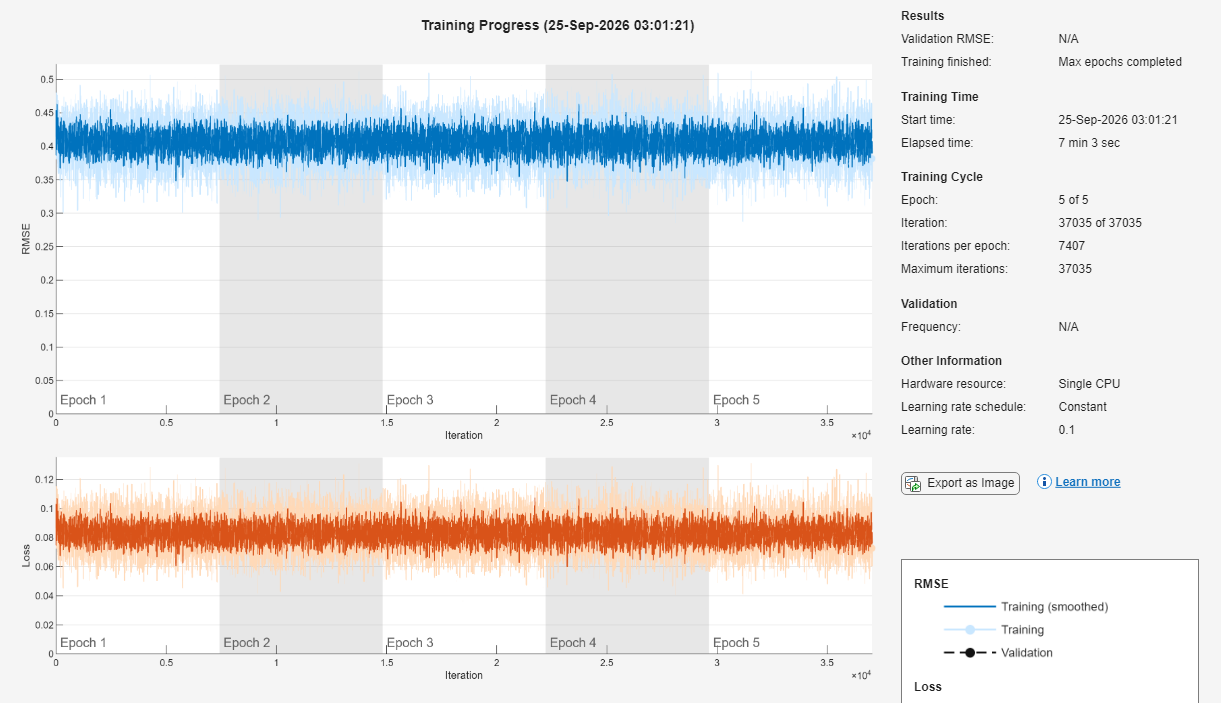

neural_net =   SeriesNetwork with properties:

         Layers: [11×1 nnet.cnn.layer.Layer]
     InputNames: {'imageinput'}
    OutputNames: {'regressionoutput'}


% Feel free to experiment with the training options

%IDEAS:
% - train on GPU


training_options = trainingOptions( "sgdm", ...
                                    InitialLearnRate=0.1, ...
                                    MaxEpochs=7, ...
                                    Shuffle="every-epoch", ...
                                    Plots="training-progress");
neural_net = trainNetwork(reshaped_features, feature_labels, network_layers, training_options)

## Step 4: Test the neural network against unseen data

### A) Load the testing dataset

load("datasets\testing_dataset.mat")

You need to apply the same preprocessing steps as you did for your training data

### B) Filter the data

Refer to **Step 3** of the **Preprocessing** section in **Notebook 2**.

%%%%%%%%%%%%%%%%%%%%%%%%% CHANGE THIS CODE %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Added what we did for filtering in notebook 02

sample_rate = 30000; % Change this random value to the actual value of the sample rate
% What cutoff frequency (in Hz) would you use for a highpass filter?
cut_off_freq = 750; % Change this random value

filt_order = 4;
norm_cut_off = cut_off_freq / (sample_rate/2);
[b, a] = butter(filt_order, norm_cut_off, 'high'); % 4th order highpass filter
ch_init_conds = zeros(filt_order, 6); %initial conditions for filter for all channels
[filt_neural_data, ~] = FilterX(b, a, testing_data.raw_neural_data, ch_init_conds);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

### C) Generate neural features from the testing dataset

Refer to the **Feature Extraction** section in **Notebook 2.**

%%%%%%%%%%%%%%%%%%%%%%%%% CHANGE THIS CODE %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

spike_locations = zeros(size(filt_neural_data))

spike_locations =      0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0


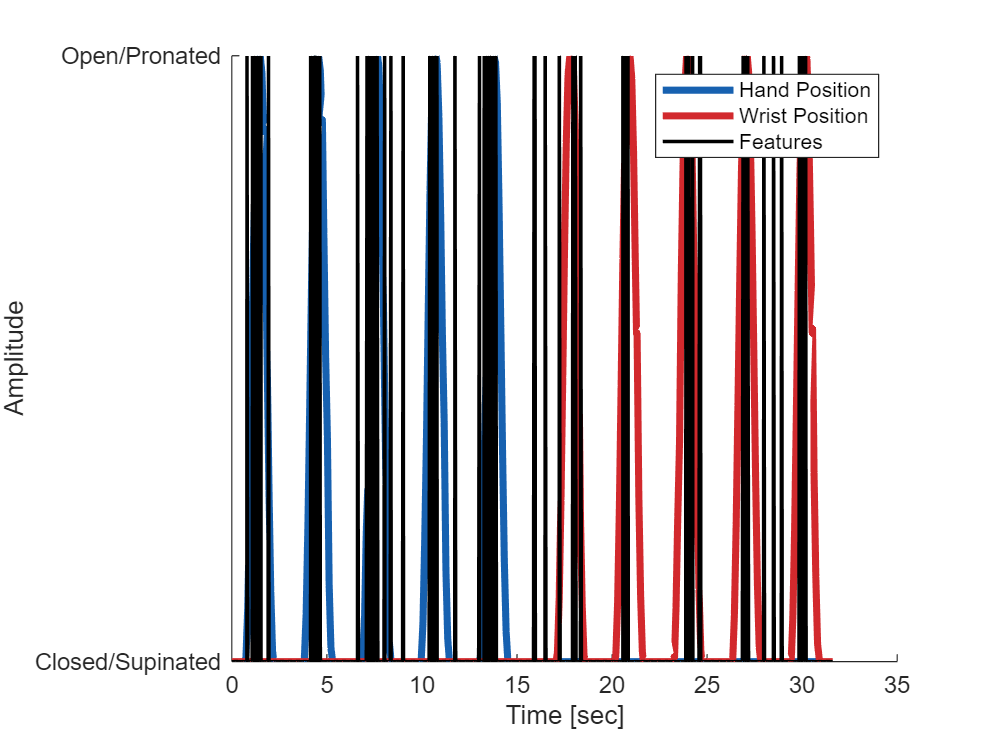


% First need to get the spike locations of the testing dataset.
thresh = zeros(1,6);

for i = 1:6
    thresh(1,i) = 4.5*rms(filt_neural_data(:,i));
end
thresh(1,6) = thresh(1,6)+2;
for i = 1:6
    spike_locations(:,i) = filt_neural_data(:,i) > thresh(1,i);
    spike_locations(:,i) = double(spike_locations(:,i));
end
filt_neural_data = double(filt_neural_data);





% Feature extraction variable definitions
n_kinematic_samples = length(testing_data.hand_kinematics);
n_neural_samples = size(spike_locations, 1);
n_chans = size(spike_locations, 2);


% Feature Extraction Method 1: Binning

% Bin spike counts per channel into windows that match the number of
% kinematic samples

bin_size = floor(n_neural_samples / n_kinematic_samples);

test_features_binned = zeros(n_kinematic_samples, n_chans);

for chan_idx = 1:n_chans
    for bin_idx = 1:n_kinematic_samples
        idx_start = (bin_idx - 1)*bin_size + 1;
        idx_end = min(idx_start + bin_size - 1, n_neural_samples);
        % Spike count in this bin = firing rate proxy for this channel
        test_features_binned(bin_idx, chan_idx) = sum(spike_locations(idx_start:idx_end, chan_idx));
    end
end

assert(length(test_features_binned) == length(testing_data.hand_kinematics), "EXPECTED EQUAL LENGTH!")
test_features_binned = normalize(test_features_binned, "range", [0 1]);
plot_features(testing_data, test_features_binned);



% Feature Extraction Method 2: Simple Exponential Smoothing (SES)

% Smooths the signal based on alpha (the TAs mentioned that filters can be
% used as feature extraction methods)

alpha = 0.1

alpha = 0.1000

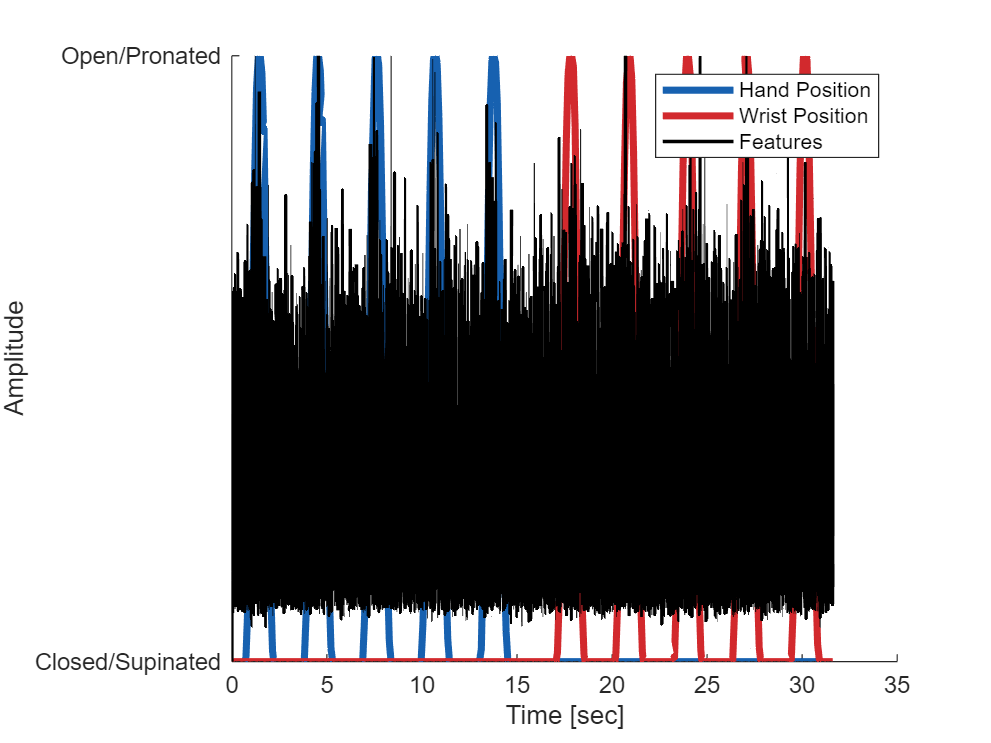


test_features_SES = zeros(n_neural_samples, n_chans);
absfiltered = abs(filt_neural_data);
for i  = 2:n_neural_samples
    for j = 1:n_chans
        test_features_SES(i,j) = alpha*absfiltered(i,j) + (1-alpha)*test_features_SES(i-1,j);
    end
end

assert(length(test_features_SES) == length(testing_data.hand_kinematics), "EXPECTED EQUAL LENGTH!")
test_features_SES = normalize(test_features_SES, "range", [0 1]);
plot_features(testing_data, test_features_SES);

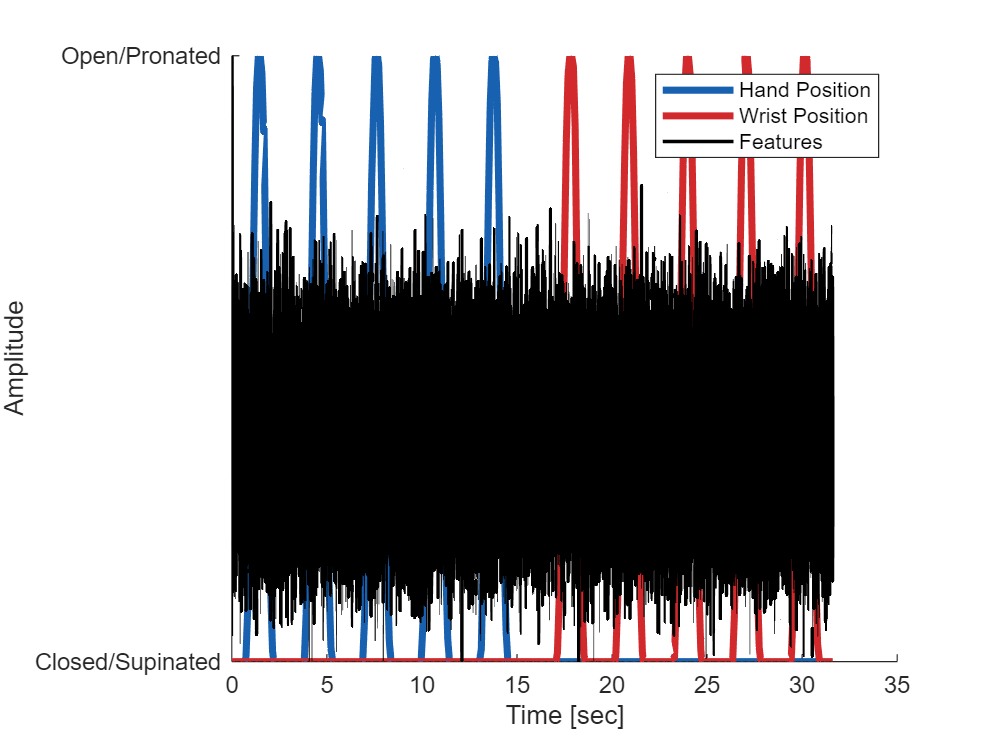




% Feature Extration Method 3: Mean - Centered Zero Crossings and Zero Crossing Rates

%Counts the amount of time the signal crosses zero over time using a
%sliding window and the rates

sig = zeros(n_neural_samples, n_chans);
test_features_ZC = zeros(n_neural_samples, n_chans);
test_features_ZCR = zeros(n_neural_samples, n_chans);
sigsum = zeros(n_neural_samples, n_chans);
trans = zeros(n_neural_samples, n_chans);
win_size = 300;
sig(1,:) = filt_neural_data(1,:) >= 0;
meansigsum = zeros(n_neural_samples,n_chans);
for j = 1:n_chans
    for i = 2:n_neural_samples
        if filt_neural_data(i,j) >0 || filt_neural_data(i,j) == 0
                sig(i,j) = 1;
        else
                sig(i,j) = 0;
        end
        trans(i,j) = abs(sig(i,j)-sig(i-1,j));
        if i > win_size
          sigsum(i,j) = sigsum(i-1,j) + trans(i,j) - trans(i-win_size,j);
          meansigsum(i,j) = meansigsum(i-1,j) + (sigsum(i,j) - sigsum(i-win_size,j))/win_size;
        else
          win_size_len = max(1, i-1);
          sigsum(i,j) = sigsum(i-1,j) + trans(i,j) - trans(i-win_size_len,j);
          meansigsum(i,j) = mean(sigsum(1:i,j));
        end
        test_features_ZC(i,j) = sigsum(i,j)-meansigsum(i,j);
        test_features_ZCR(i,j) = test_features_ZC(i,j)/win_size_len;
    end
end


assert(length(test_features_ZC) == length(testing_data.hand_kinematics), "EXPECTED EQUAL LENGTH!")
test_features_ZC = normalize(test_features_ZC, "range", [0 1]);
plot_features(testing_data, test_features_ZC);

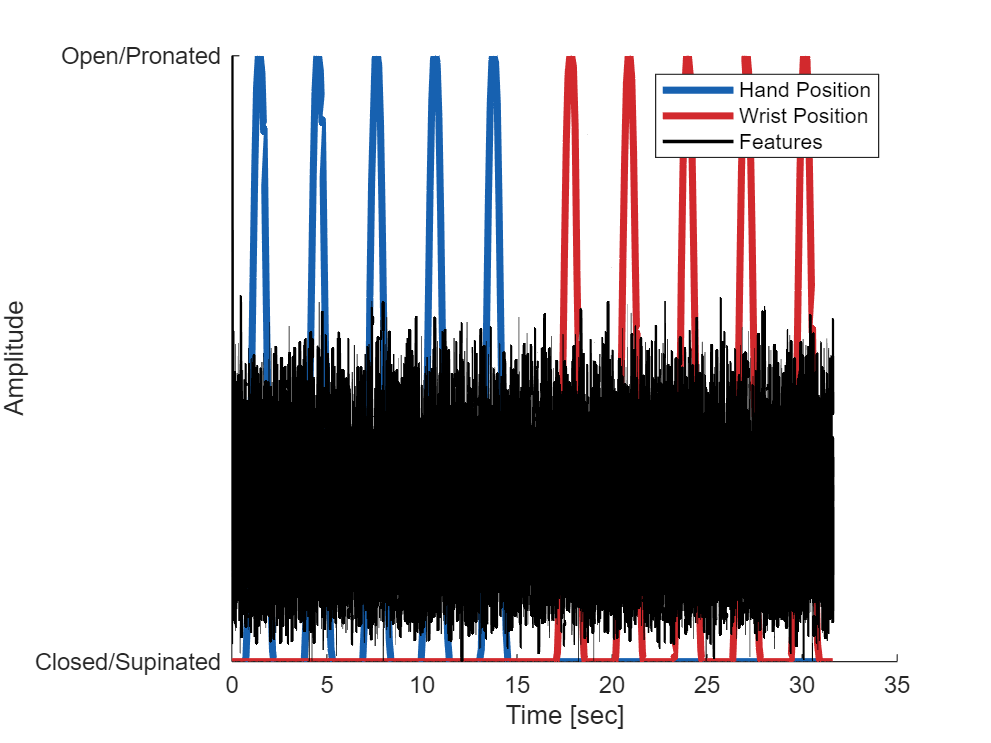




assert(length(test_features_ZCR) == length(testing_data.hand_kinematics), "EXPECTED EQUAL LENGTH!")
test_features_ZCR= normalize(test_features_ZCR, "range", [0 1]);
plot_features(testing_data, test_features_ZCR);

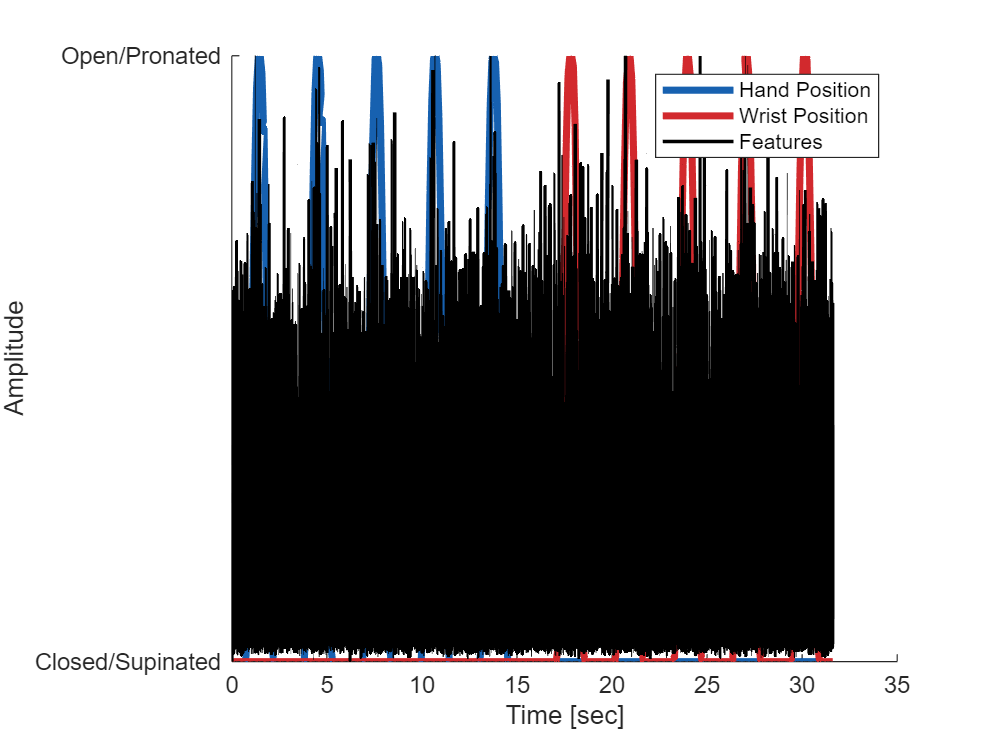



% Feature Extraction Method 5: Sliding Root Mean Square Window
%test_features_RMS = sqrt(movmean(filt_neural_data.^2, win_size));
rms_win_size = 5;
test_features_RMS = zeros(n_neural_samples, n_chans);
sq = filt_neural_data.^2;
sumsq = zeros(n_neural_samples, n_chans);
sumsq(1,:) = sq(1,:);

for i = 2:n_neural_samples
    if i > rms_win_size
        sumsq(i,:) = sumsq(i-1,:) + sq(i,:) - sq(i-rms_win_size,:);
    else
        sumsq(i,:) = sumsq(i-1,:) + sq(i,:);
    end
    win_len = min(i, rms_win_size);
    test_features_RMS(i,:) = sqrt(sumsq(i,:)/win_len);
end


assert(length(test_features_RMS) == length(testing_data.hand_kinematics), "EXPECTED EQUAL LENGTH!")
test_features_RMS= normalize(test_features_RMS, "range", [0 1]);
plot_features(testing_data, test_features_RMS);

test_features_all = struct("binned", test_features_binned, "SES", test_features_SES, ...
                            "RMS", test_features_RMS, "ZC", test_features_ZC, "ZCR", test_features_ZCR);
test_neural_features = test_features_all.(feature_type);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
assert(length(test_neural_features) == length(testing_data.hand_kinematics), "EXPECTED EQUAL LENGTH!")
test_neural_features = normalize(test_neural_features, "range", [0 1]);

### D) Reshape the neural features

Refer to **Step 3** of **Notebook 3**

n_features = width(test_neural_features);
n_timestamps = length(testing_data.hand_kinematics);
image_input_size = [n_features, 1, 1];
reshaped_features = zeros([image_input_size, n_timestamps]);
for timestamp = 1:n_timestamps
    reshaped_features(:,:,:, timestamp) = test_neural_features(timestamp,:)';
end

### E) Predict the testing kinematics based on your generated features

kinematics_predicted = predict(neural_net, reshaped_features);
%should this be for training or testing
kinematics_observed = testing_data.hand_kinematics;

### D) Compare your predictions with the actual values of the kinematics

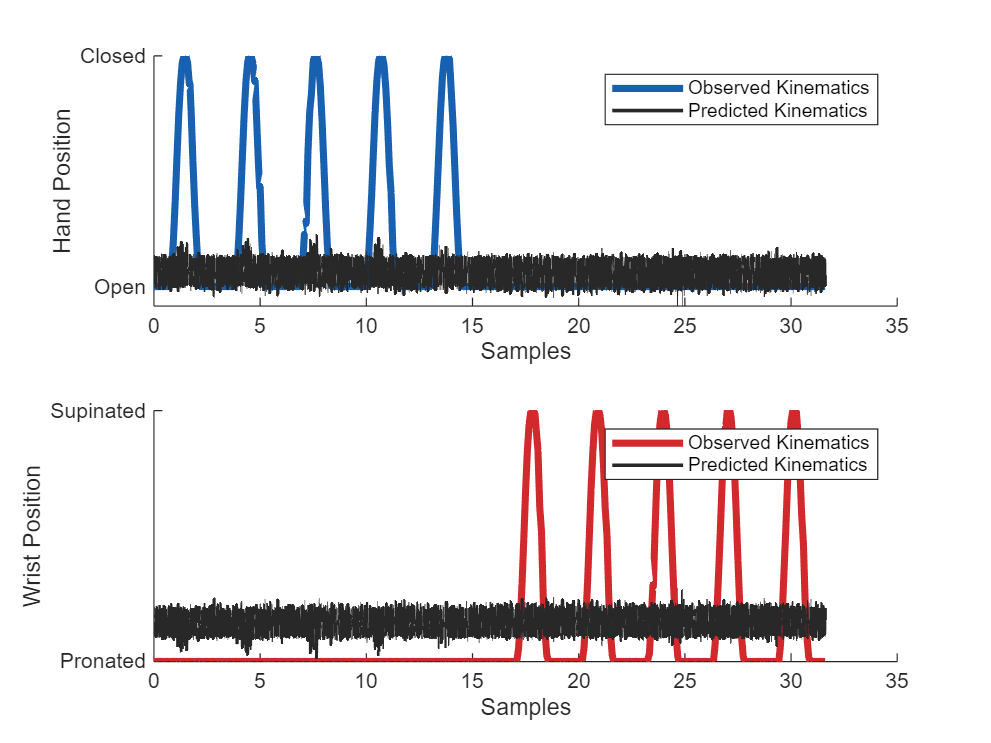

figure
tlo = tiledlayout('flow');
t = (0:1:length(kinematics_observed)-1)/testing_data.sample_rate;
nexttile
hold on
plot(t, kinematics_observed(:,1), 'LineStyle','-','Color', "#1761B0", 'LineWidth', 3)
plot(t, kinematics_predicted(:,1), 'LineStyle','-','Color', "#282828", 'LineWidth', 1.5)
hold off
xlabel("Samples")
ylabel("Hand Position")
yticks([0 1])
yticklabels({"Open" "Closed"})
legend(["Observed Kinematics", "Predicted Kinematics"])

nexttile
hold on
plot(t, kinematics_observed(:,2), 'LineStyle','-','Color', "#D2292D", 'LineWidth', 3)
plot(t, kinematics_predicted(:,2), 'LineStyle','-','Color', "#282828", 'LineWidth', 1.5)
hold off
legend(["Observed Kinematics", "Predicted Kinematics"])
xlabel("Samples")
ylabel("Wrist Position")
yticks([0 1])
yticklabels({"Pronated" "Supinated"})
legend(["Observed Kinematics", "Predicted Kinematics"])

% Helper Functions
function fig_handle = plot_raw_data(training_data)
[num_samples, num_chans] = size(training_data.raw_neural_data);
timestamps = (1:num_samples)/training_data.sample_rate;

fig_handle = figure;
fig_raw = tiledlayout("flow");
for i = 1:num_chans
    ax_handles{i} = nexttile;
    plot(timestamps, training_data.raw_neural_data(:,i))
    title(sprintf('Channel %02d', i))
    xlabel('Time [sec]')
    ylabel('Amplitude [\muV]')
end
title(fig_raw, 'Raw Neural Data')
linkaxes([ax_handles{:}], 'xy');
ylim([-50, 50])
end


function fig_handle = plot_filt_data(neural_data, sample_rate)
[num_samples, num_chans] = size(neural_data);
timestamps = (1:num_samples)/sample_rate;

fig_handle = figure;
fig_raw = tiledlayout("flow");
for i = 1:num_chans
    ax_handles{i} = nexttile;
    plot(timestamps, neural_data(:,i))
    title(sprintf('Channel %02d', i))
    xlabel('Time [sec]')
    ylabel('Amplitude [\muV]')
end
title(fig_raw, 'Filtered Neural Data')
linkaxes([ax_handles{:}], 'xy');
ylim([-50, 50])
end


function fig_handle = plot_spike_trains(spike_locations, training_data)
fig_handle = figure;
t = (0:1:length(spike_locations)-1)'/training_data.sample_rate;
raster_handle = stackedplot(t, [training_data.hand_kinematics, spike_locations], LineWidth=1.5);
raster_handle.Color = "black";
raster_handle.LineProperties(1).Color = "#0072BD";
raster_handle.LineProperties(2).Color = "red";
raster_handle.DisplayLabels = ["Hand Position", "Wrist Position", "CH 01", "CH 02", "CH 03", "CH 04", "CH 05", "CH 06"];
raster_handle.XLabel = "Time [sec]";
raster_handle.Title = "Raster Plot";
end


function spike_waveform_container = get_action_potentials(spike_trains, neural_data, plot_title)
[~, n_chans] = size(neural_data);
figure()
sgtitle(plot_title)
spike_waveform_container = cell(n_chans,1);
for chan=1:n_chans
    neg_offset = -3;
    pos_offset = 18;
    spike_locations = spike_trains(:,chan);
    spike_locations = find(spike_locations == 1);
    spike_count = sum(spike_trains);
    spikes = cell(1, spike_count(chan));

    subplot(2, 3, chan)
    for spike_idx = 1:length(spikes)
        idx_start = spike_locations(spike_idx) + neg_offset;
        idx_end = spike_locations(spike_idx) + pos_offset;
        try
            spikes{spike_idx} = neural_data(idx_start:idx_end, chan);
            plot(0:33:700, spikes{spike_idx});
        catch
        end
        hold on;
        spike_waveform_container{chan} = spikes;
    end
    xlabel('Time (\mus)')
    ylabel('Voltage (\muV)')
    hold off
    title(['Channel ' num2str(chan)])
    subtitle(['Spikes: ' num2str(length(spikes))])
    ylim([-40, 40])
end
end

function fig_handle = plot_features(training_data, neural_features)
fig_handle = figure;
hold on
t = (0:1:length(training_data.hand_kinematics)-1)/training_data.sample_rate;
plot(t, training_data.hand_kinematics(:,1), 'LineStyle','-','Color', "#1761B0", 'LineWidth', 3)
plot(t, training_data.hand_kinematics(:,2), 'LineStyle','-','Color', "#D2292D", 'LineWidth', 3)
plot(t, neural_features,'Color',"#000000" ,'LineWidth', 1.5)
hold off
box off
ylim([0 1])
yticks([0 1])
yticklabels({"Closed/Supinated", "Open/Pronated"})
xlabel("Time [sec]")
ylabel("Amplitude")
legend(["Hand Position", "Wrist Position", "Features"])
end
